# **Instruction**

Run the helperACCSetUp script,which initializes data used by the model, such as the vehicle and ACC design parameters.

helperACCSetUp;

3 states removed.


Run the helperManeuverSetUp script,which initializes data used by the maneuver.

helperManeuverSetUp;

Open the E23 model.

mdl = 'Studienarbeit';
open_system(mdl);

Open the Commandd APP. In Commandd APP you` can set the initial value of ego vehicle position,velocity,and set the command to let the vehicle switch lane. 

Commandd;

Open the Bird's-Eye Scope,and find signals,then run.

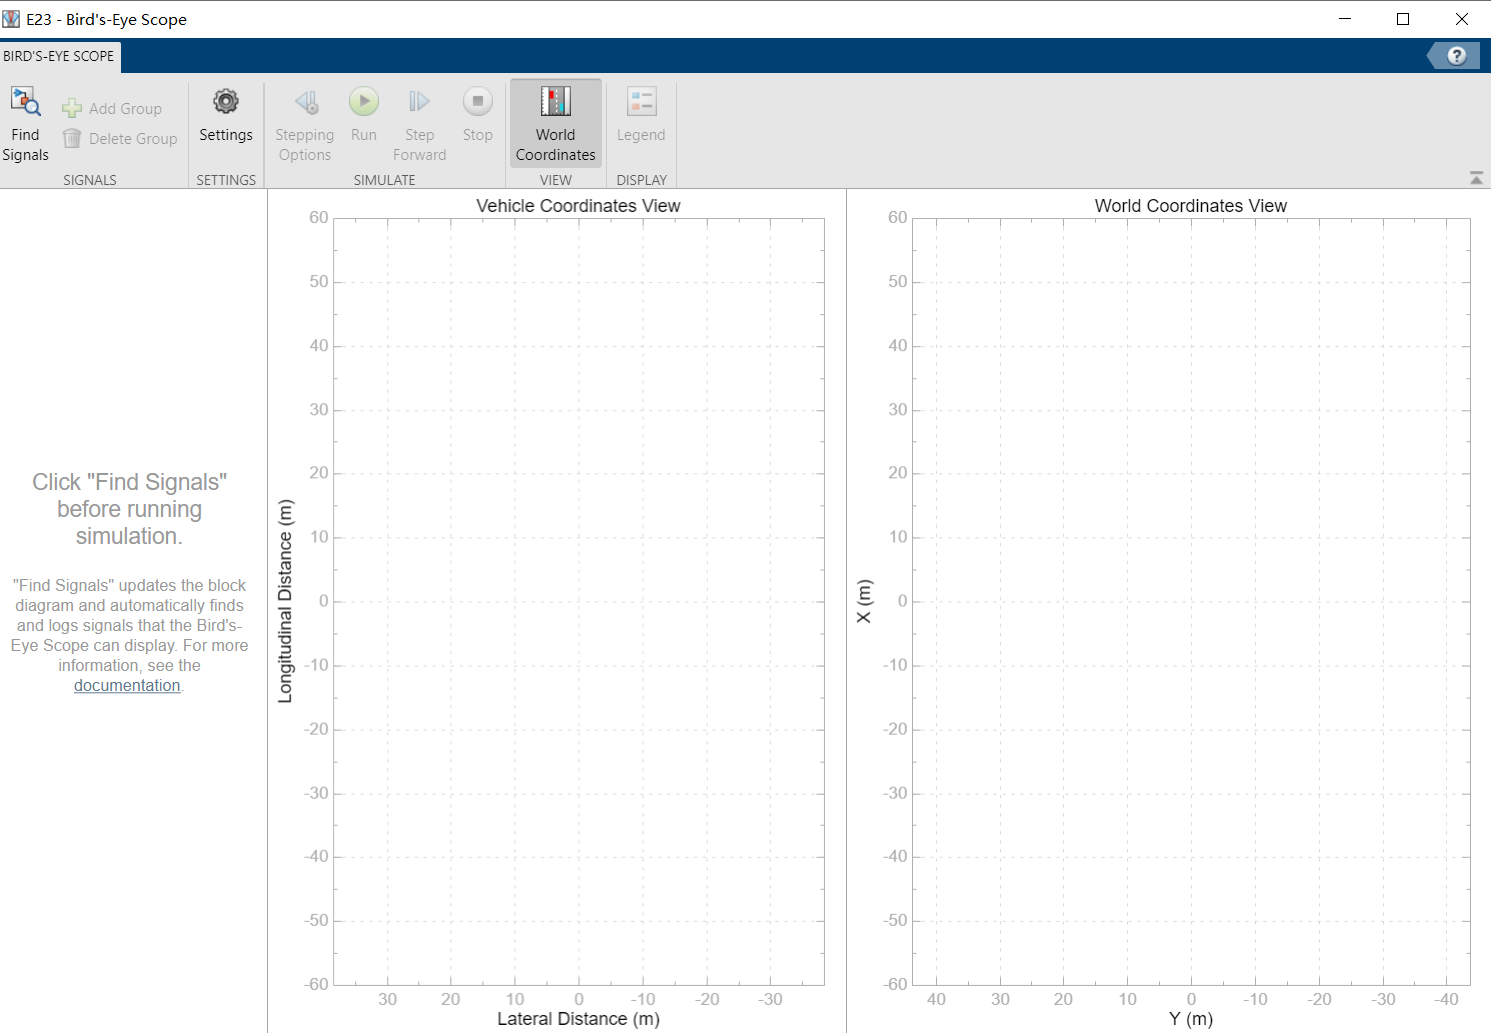

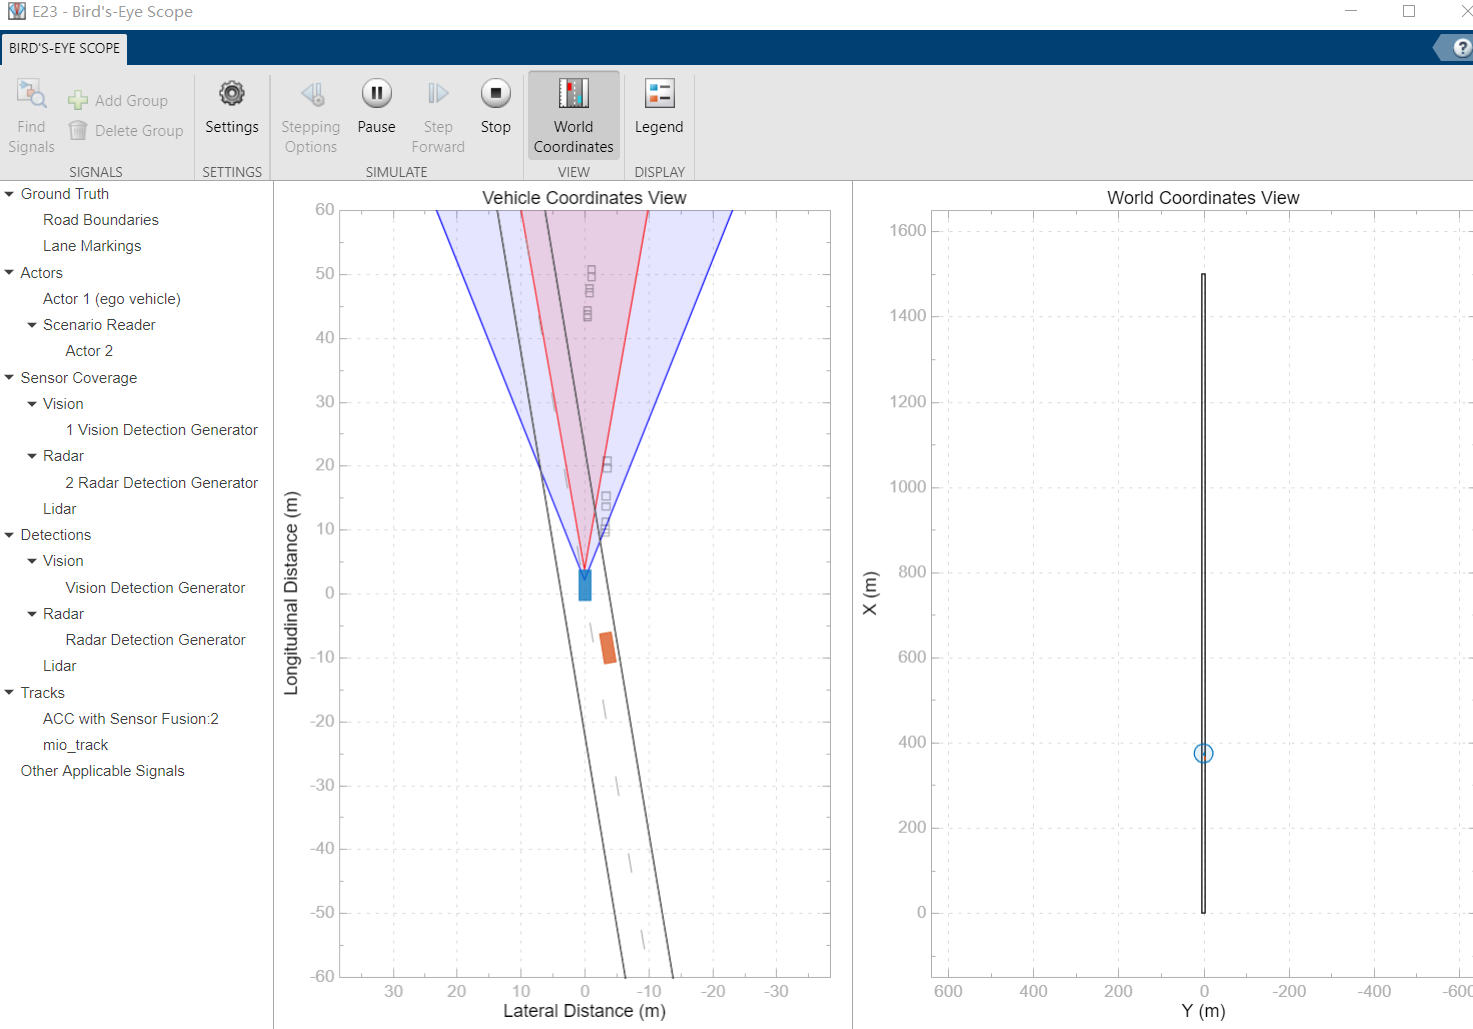

# **Introduction**

This model achieves the lane change,u-turn and lane keeping maneuvers.

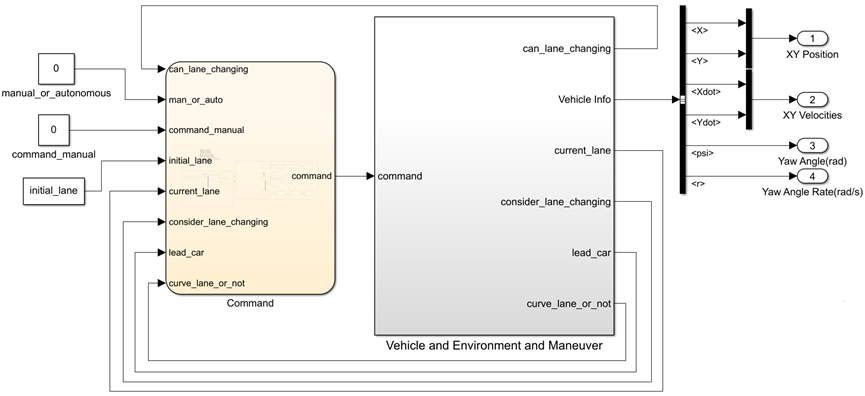

The level 1 has two parts,one is Command flowchart(L1.1),another one is Vehicle and Environment and Maneuver(L1.2).

L1.1 outputs the command signal to L1.2,L1.2 will make different maneuver according to the command signal and output vehicle infomation.manual_or_autonomous sets the driving mode of vehicle,command_manual indicate the vehicle to make different maneuver,both can be modified in the GUI.

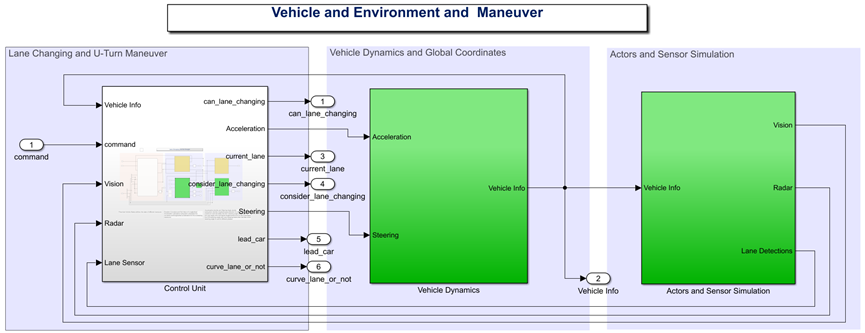

Level 2 has three subsystems:

(1)Control Unit subsystem(L2.1) takes the command signal as input to use different algorithm to achieve different maneuver,outputs  information to the vehicle dynamics model and L1.1.

(2)Vehicle Dynamics subsystem(L2.2) models the vehicle dynamics with the Bicycle  Model - Force Input block from the Automated Driving Toolbox.

(3) The Actors and Sensor Simulation(L2.3) subsystem generates the synthetic sensor data required for tracking and sensor fusion.

# **Control Unit(L2.1)**

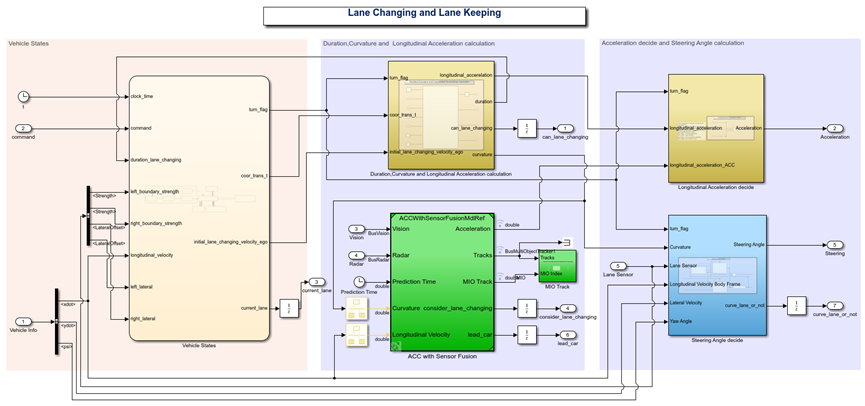

L2.1 is the level 3,and there are 5 parts:

(1)Vehicle States(L3.1) defines different vehicle states,each state correspond to a  maneuver,it will output the needed information to the algorithm.

(2)Duration,Curvature and Longitudinal Acceleration calculation(L3.2) calculates the acceleration,curvature and duration for different maneuver,outputs the can_lane_changing flag to indicate whether it is allowed to change lane.

(3)ACC with Sensor Fusion(L3.3) achieves the ACC,it outputs the consider_lane_changing and lead_car flags which are used in the autonomous mode in L1.1.

(4)Longitudinal Acceleration decide(L3.4) decides which acceleration to use for different maneuver.

(5)Steering Angle decide(L3.5) decides which steering angle to use for different maneuver,outpus the curve_lane_or_not to L1.1.

# **Vehicle States(L3.1)**

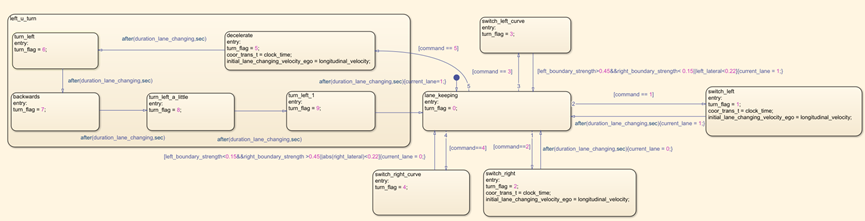

The Vehicle State flowchart defines 6 main states:

1.switch left and right straight

2.switch left and right curve

3.left u-turn

4.lane keeping

Left u-turn state has many substates.The command signal determines the state of the vehicle.Each state outputs a turn_flag,which indicates the vehicle to make a correspongding maneuver.The coor_trans_t is used to make coordinate system transformation.After every maneuver the current_lane will be updated.

# **Duration,Curvature and Longitudinal Acceleration calculation(L3.2)**

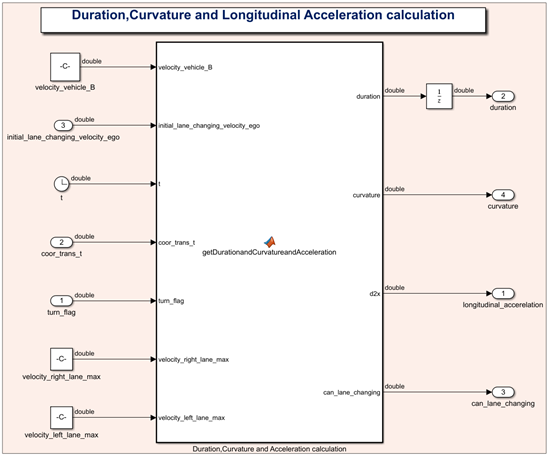

This matlab function calculates the duration,longitudinal acceleration and curvature for different maneuver,it also outputs the can_lane_changing flag,but now it is set to one.

The three constants can be modified in GUI.

# **Adaptive Cruise Controller with Sensor Fusion(L3.3)**

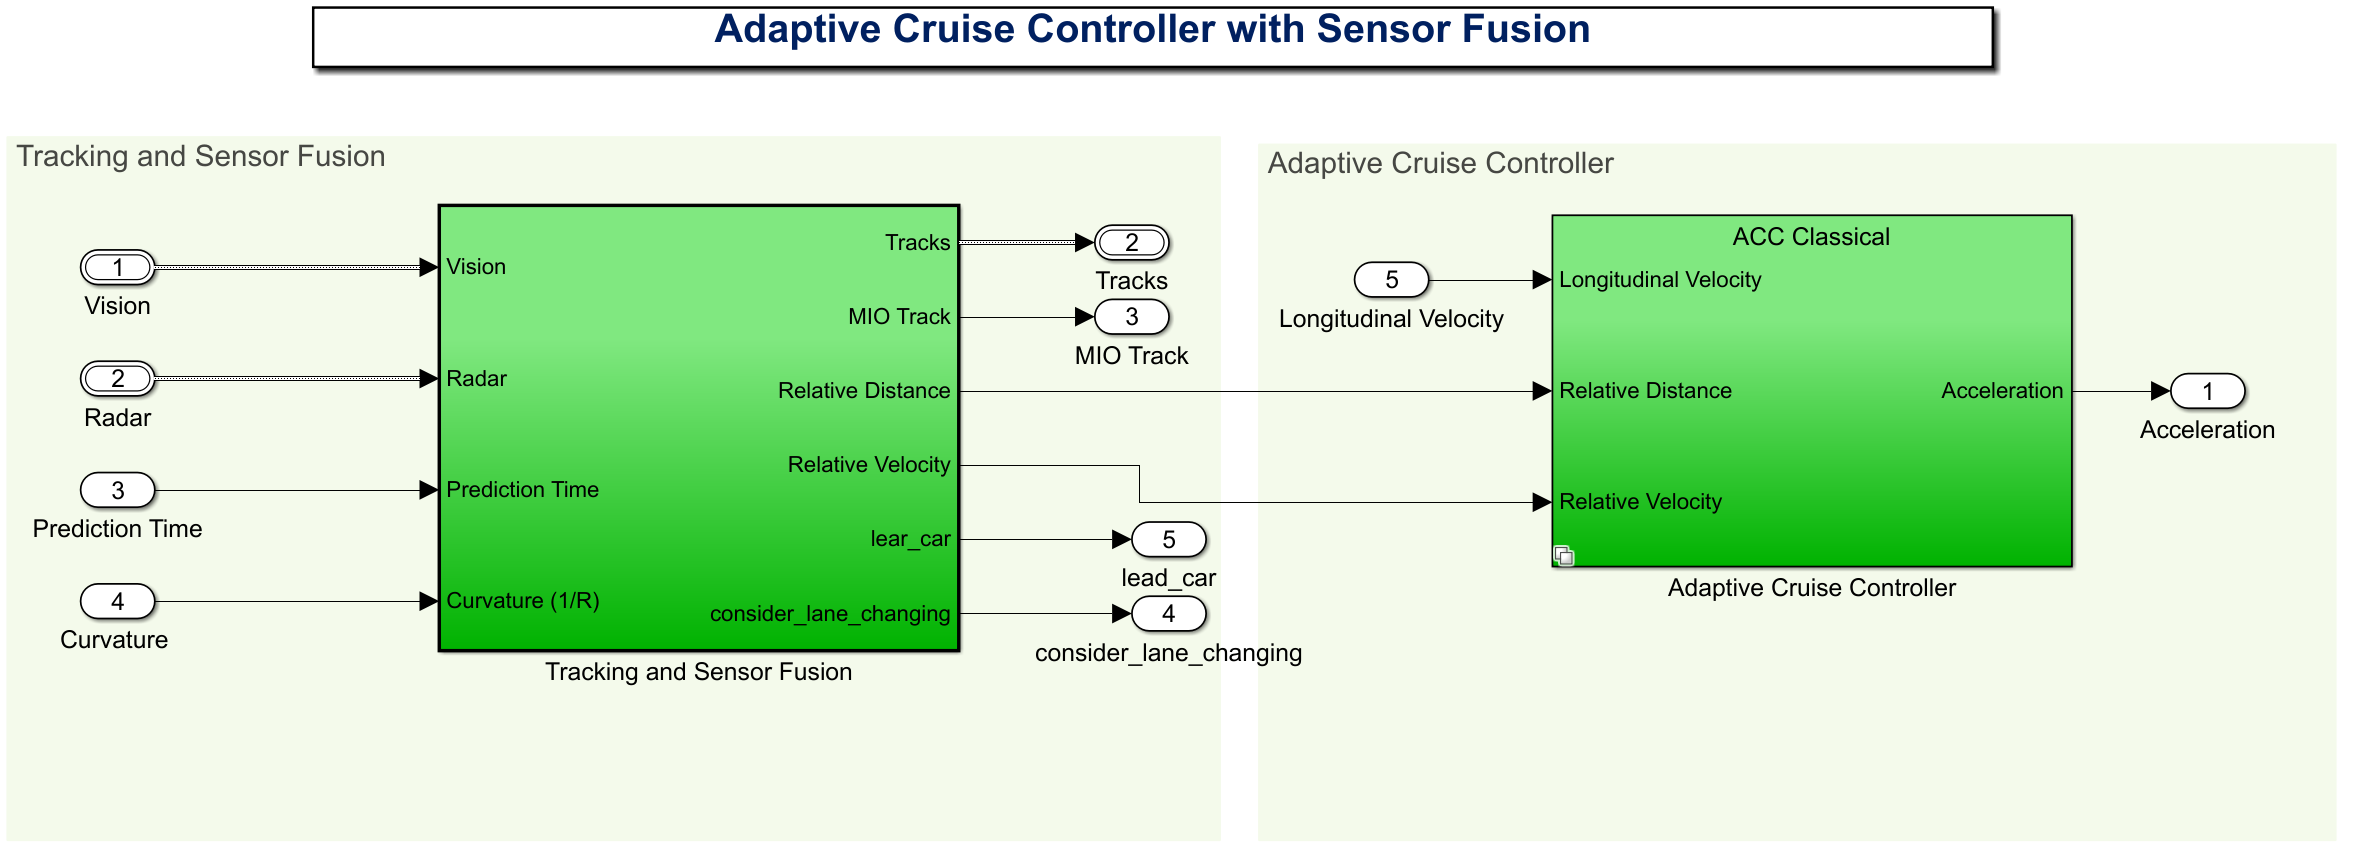

The detail of this subsystem can be found in the website:

[https://www.mathworks.com/help/driving/examples/adaptive-cruise-control-with-sensor-fusion.html](https://www.mathworks.com/help/driving/examples/adaptive-cruise-control-with-sensor-fusion.html)

The Tracking and Sensor Fusion subsystem processes vision and radar detections coming from the Vehicle and Environment subsystem and generates a comprehensive situation picture of the environment around the ego vehicle. Also, it provides the ACC with an estimate of the closest car in the lane in front of the ego vehicle.It also output lear_car and consider_lane_changing which are used in autonomous mode.

# **Longitudinal Acceleration decide(L3.4)**

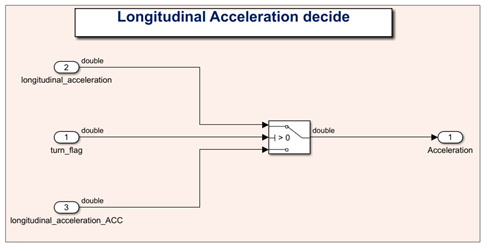

When turn_flag = 0,which means the vehicle is keeping its lane,the acceleration is from ACC,ohterwise it is from L3.2.

# **Steering Angle Decide(L3.5)**

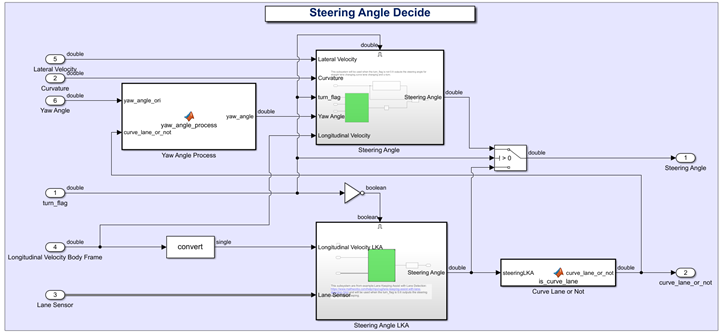

There are two subsystems for steering angle calculating:

(1)Steering Angle(L3.5.1),used for maneuvers except lane keeping.

(2)Steering Angle LKA(L3.5.2),used for lane keeping

L3.5.1 is enabled when turn_flag is larger than zero,L3.5.2 is enabled when turn_flag is zero.

The Yaw Angle Process function is used to modify the yaw angle.After processing,the vehicle can make straight lane change when the yaw angle is larger than ninety degree.

The Curve Lane or Not function is used to indicate the situation of the road,the input is the steering angle from L3.5.2,the idea is when the steering angle is larger than a certain Threshold,the road is curve,set the curve_lane_or_not to 1.

# **Driver Steering Model(L3.5.1)**

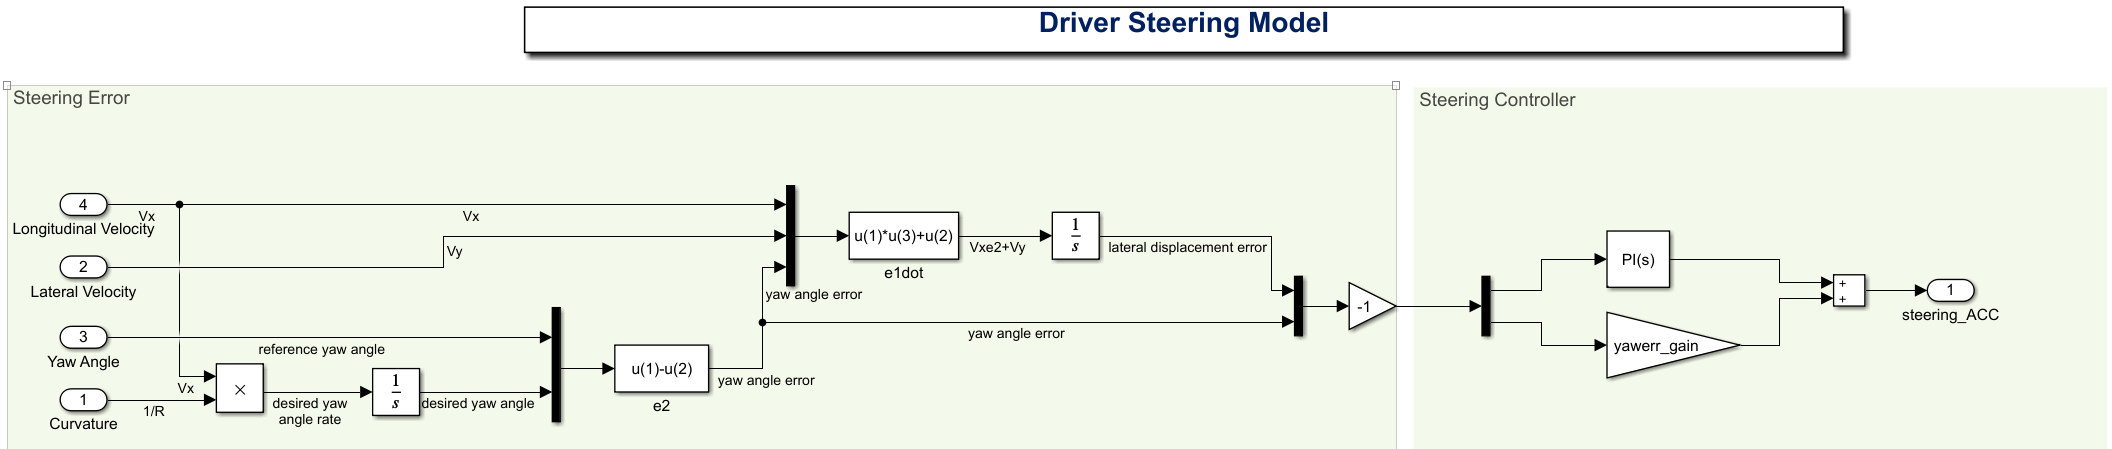

The detail of this subsystem of this subsystem can be found in the website:

[https://www.mathworks.com/help/driving/examples/adaptive-cruise-control-with-sensor-fusion.html](https://www.mathworks.com/help/driving/examples/adaptive-cruise-control-with-sensor-fusion.html)

# **Lane Keeping Assist(L3.5.2)**

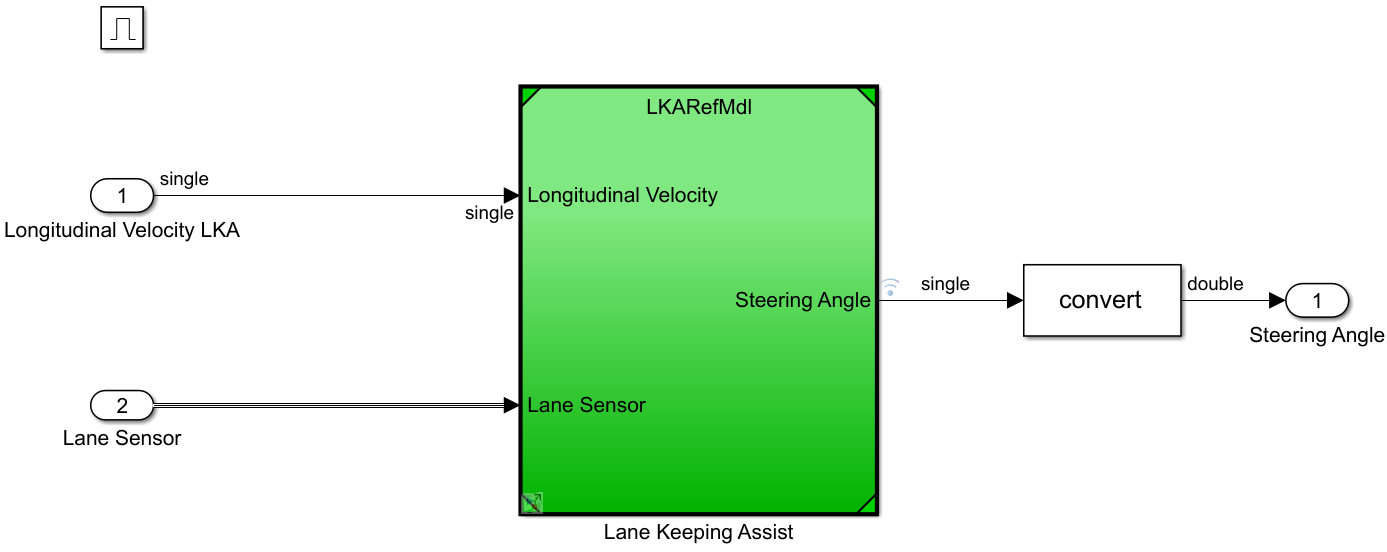

The detail of this subsystem of this subsystem can be found in the website:

[https://www.mathworks.com/help/mpc/ug/lane-keeping-assist-with-lane-detection.html](https://www.mathworks.com/help/mpc/ug/lane-keeping-assist-with-lane-detection.html)